%%OTA-less ADC
%%1b 1st order decimation ADC
clc;
clear;
addpath('../utilities');

%Hadamard
m = 256;%Hadamard order
H_matrix = mtxdya(m);
% H_matrix = strcat("H_matrix_", num2str(m), ".mat");
% load(H_matrix);  
f_hadamard = 5e8;
T_hadamard = 1/f_hadamard;

%coherent sampling

dec_points = 32;
Mpoints = (dec_points+2)*2*m;

%parameters
f_s = 5e8;
Ns = [7, 67, 193, 367, 1999, 7879];
f_sigs = f_s*Ns/2^14;

%ADC parameters
VFS = 0.8;
NOB = 20;
ENOBs = 7:12;
Vrmss = VFS./(2.^ENOBs)./4;


input_sequence = H_matrix(:,5);

BW = 2.5e8/m;
osr = f_s/BW/2;
osr_eff = f_s./f_sigs./2;
delay = 1e-12;

%timing configurations
T_run = Mpoints*T_hadamard;
t = linspace(0, T_run*8/10, Mpoints*8/10);

## Run the model in series to mimic parallel channels

SNDRs = zeros([length(f_sigs), length(Vrmss)]);
output_ENOBs = zeros([length(f_sigs), length(Vrmss)]);
pulse_width = 0.001;
for i=1:length(f_sigs)
    f_sig = f_sigs(i);
    channel_2048samples = zeros(dec_points*2,m);
    for j=1:length(Vrmss)
        Vrms = Vrmss(j);
        for k=1:8:m
            sml = sim("mdl_Noramlized_LPF_SAR_parallel.slx");
        
            channel_2048samples(:,k) = sml.dec_out0(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+1) = sml.dec_out1(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+2) = sml.dec_out2(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+3) = sml.dec_out3(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+4) = sml.dec_out4(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+5) = sml.dec_out5(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+6) = sml.dec_out6(end-dec_points*2+1:end, 1);
            channel_2048samples(:,k+7) = sml.dec_out7(end-dec_points*2+1:end, 1);
        end
    
        inv_tf_LPF = inverse_transform(m, channel_2048samples);
        data = inv_tf_LPF';
        data_length = length(data); 
        periodogram_length = data_length;
        num_segments = data_length/periodogram_length;
        plotYN = 0; plotAll = 0; plotHold = 0;
        [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
            = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
        SNRs(i, j) = SNDR;
        output_ENOBs(i, j) = ENOB;
    end
end

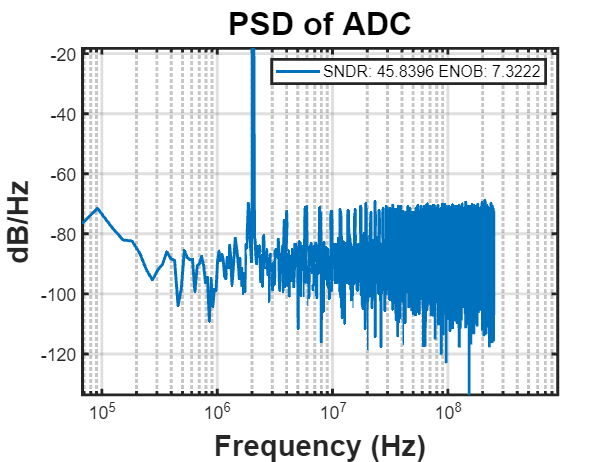

f_sig = f_sigs(2);
Vrms = Vrmss(end);
seed_offset = 0;
pulse_width = 0.025;
for k=1:8:m
    sml = sim("mdl_Noramlized_LPF_SAR_parallel.slx");

    channel_2048samples(:,k) = sml.dec_out0(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+1) = sml.dec_out1(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+2) = sml.dec_out2(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+3) = sml.dec_out3(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+4) = sml.dec_out4(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+5) = sml.dec_out5(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+6) = sml.dec_out6(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+7) = sml.dec_out7(end-dec_points*2+1:end, 1);
end

inv_tf_LPF = inverse_transform(m, channel_2048samples);
data = inv_tf_LPF';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
SNDR = num2str(SNDR);
ENOB = num2str(ENOB);
legend("SNDR: "+SNDR+" ENOB: "+ENOB);

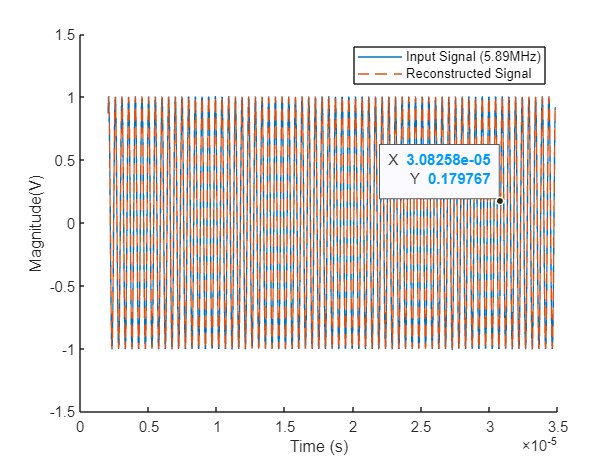

figure;
t = linspace(0, T_run, Mpoints);
t = t(end-2*dec_points*osr+1:end);
xlabel("Time (s)");
ylabel("Magnitude(V)");
hold on;
in_sig = sin(2*pi*f_sig*(t));
plot(t, inv_tf_LPF * 1/0.34941);
plot(t, in_sig, '--');
hold off;
legend('Input Signal (5.89MHz)', 'Reconstructed Signal')

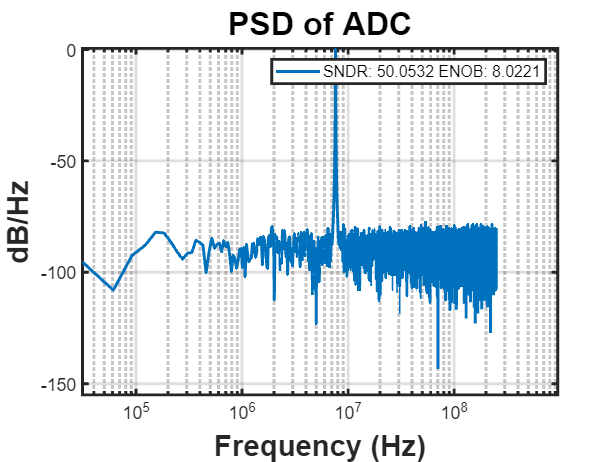

data = inv_tf_LPF';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
SNDR = num2str(SNDR);
ENOB = num2str(ENOB);
legend("SNDR: "+SNDR+" ENOB: "+ENOB);

f_sig2 = f_sigs(4)

f_sig2 = 1.1200e+07

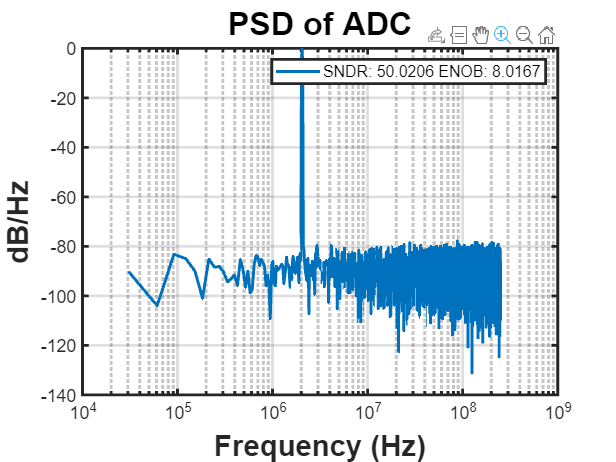

Vrms = Vrmss(end);
seed_offset = 300;
pulse_width = 0.001;
channel_2048samples2 = zeros(dec_points*2,m);
for k=1:8:m
    sml = sim("mdl_Noramlized_LPF_SAR_parallel.slx");

    channel_2048samples2(:,k) = sml.dec_out0(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+1) = sml.dec_out1(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+2) = sml.dec_out2(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+3) = sml.dec_out3(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+4) = sml.dec_out4(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+5) = sml.dec_out5(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+6) = sml.dec_out6(end-dec_points*2+1:end, 1);
    channel_2048samples2(:,k+7) = sml.dec_out7(end-dec_points*2+1:end, 1);
end

inv_tf_LPF2 = inverse_transform(m, channel_2048samples2);
data = inv_tf_LPF2';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
SNDR = num2str(SNDR);
ENOB = num2str(ENOB);
legend("SNDR: "+SNDR+" ENOB: "+ENOB);

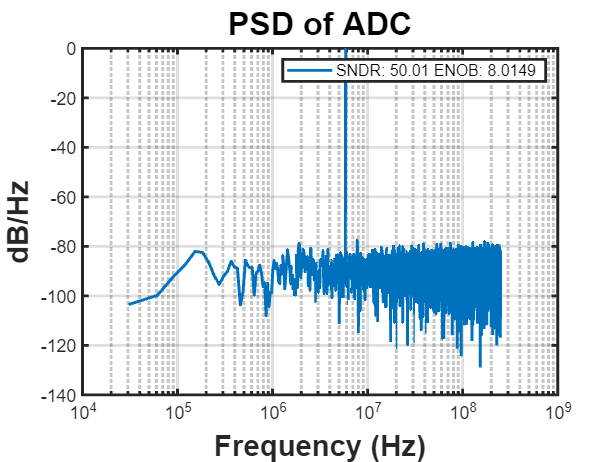

f_sig = f_sigs(3);
Vrms = Vrmss(end);
seed_offset = 0;
pulse_width = 0.001;
for k=1:8:m
    sml = sim("mdl_Noramlized_LPF_SAR_parallel.slx");

    channel_2048samples(:,k) = sml.dec_out0(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+1) = sml.dec_out1(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+2) = sml.dec_out2(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+3) = sml.dec_out3(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+4) = sml.dec_out4(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+5) = sml.dec_out5(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+6) = sml.dec_out6(end-dec_points*2+1:end, 1);
    channel_2048samples(:,k+7) = sml.dec_out7(end-dec_points*2+1:end, 1);
end

inv_tf_LPF = inverse_transform(m, channel_2048samples);
data = inv_tf_LPF';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
SNDR = num2str(SNDR);
ENOB = num2str(ENOB);
legend("SNDR: "+SNDR+" ENOB: "+ENOB);

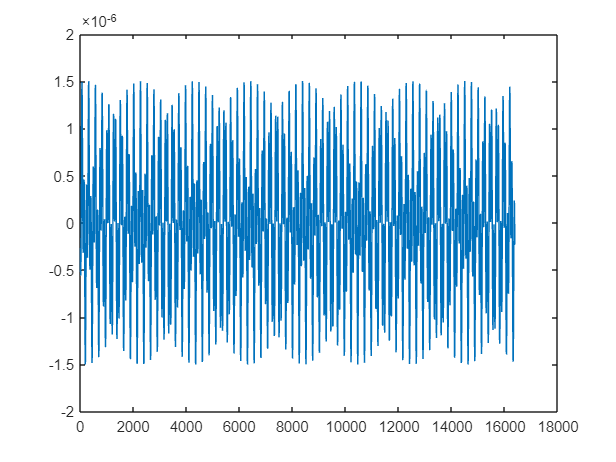

sig1_recombined = recombine(channel_2048samples, 256*64);
sig2_recombined = recombine(channel_2048samples2, 256*64);
r = cyclic_conv2(sig1_recombined, sig2_recombined);
r = reshape(r, 1, []);
plot(r)

cyclic_corr = ifft(fft(inv_tf_LPF) .* conj(fft(inv_tf_LPF2)))

cyclic_corr = 1.0e+03 *

    1.0030    1.0002    0.9917    0.9776    0.9580    0.9330    0.9027    0.8673    0.8271    0.7821    0.7327    0.6792    0.6219    0.5610    0.4970    0.4302    0.3609    0.2896    0.2167    0.1426    0.0676   -0.0077   -0.0830   -0.1579   -0.2318   -0.3044   -0.3753   -0.4441   -0.5104   -0.5738   -0.6340   -0.6905   -0.7432   -0.7917   -0.8357   -0.8750   -0.9094   -0.9386   -0.9625   -0.9810   -0.9939   -1.0012   -1.0029   -0.9989   -0.9893   -0.9741   -0.9533   -0.9272   -0.8959   -0.8595


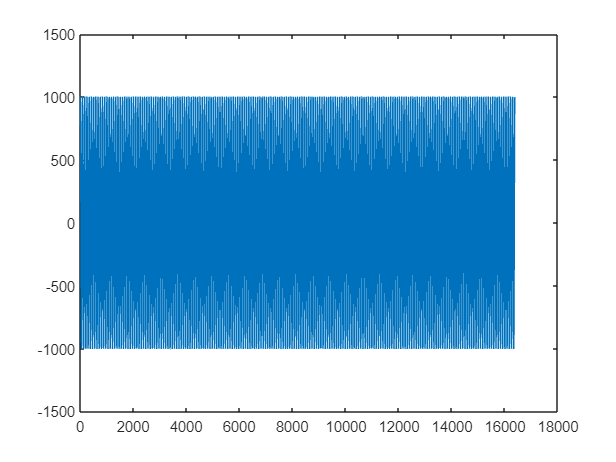

plot(cyclic_corr)

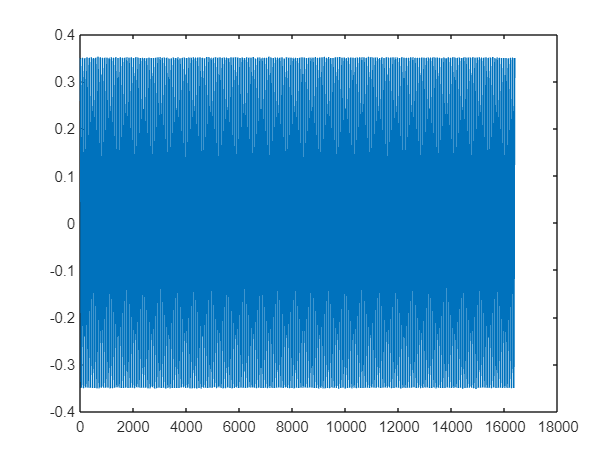

plot(inv_tf_LPF)

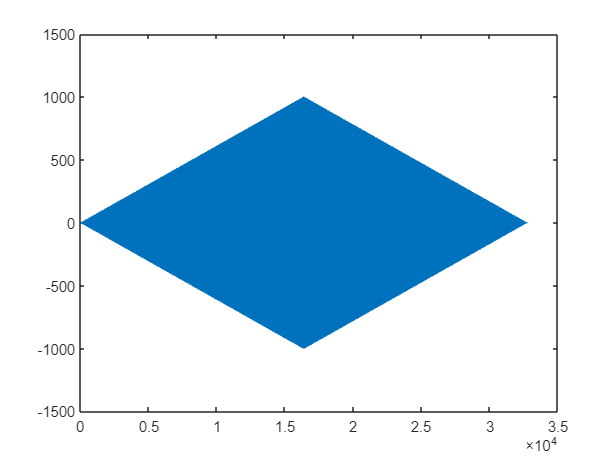

plot(cconv(inv_tf_LPF, fliplr(inv_tf_LPF2)))

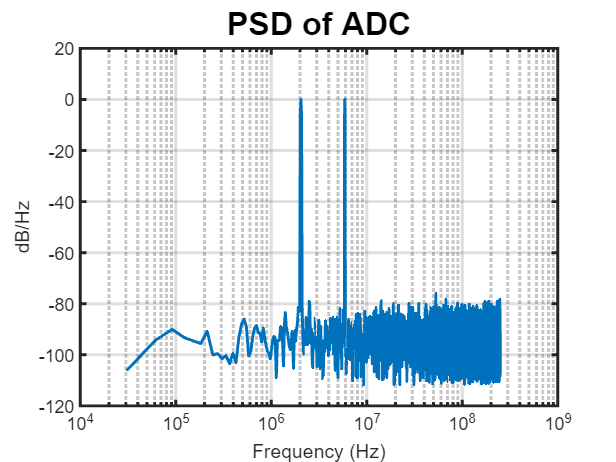

data = r';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
xlabel('Frequency (Hz)')
ylabel('dB/Hz')

SNDR = num2str(SNDR);
ENOB = num2str(ENOB);

pulse_widths = [0.0025, 0.005, 0.0075, 0.01, 0.0125, 0.015];
SNDRs = zeros(1, length(pulse_widths));
Vrms = Vrmss(end);
for j=1:length(pulse_widths)
    pulse_width = pulse_widths(j);
    for k=1:8:m
        sml = sim("mdl_Noramlized_LPF_SAR_parallel.slx");
    
        channel_2048samples(:,k) = sml.dec_out0(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+1) = sml.dec_out1(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+2) = sml.dec_out2(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+3) = sml.dec_out3(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+4) = sml.dec_out4(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+5) = sml.dec_out5(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+6) = sml.dec_out6(end-dec_points*2+1:end, 1);
        channel_2048samples(:,k+7) = sml.dec_out7(end-dec_points*2+1:end, 1);
    end

    inv_tf_LPF = inverse_transform(m, channel_2048samples);
    data = inv_tf_LPF';
    data_length = length(data); 
    periodogram_length = data_length;
    num_segments = data_length/periodogram_length;
    plotYN = 0; plotAll = 0; plotHold = 0;
    [sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
        = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
    SNDRs(j) = SNDR;
end

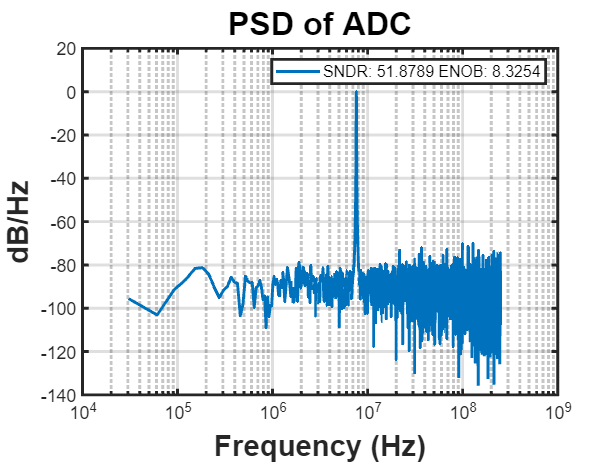

channel_vals = mean(channel_2048samples.^2, 1);
off_channels = repmat(channel_vals < 1e-8, size(channel_2048samples, 1), 1);
channel_2048samples_to = channel_2048samples;
channel_2048samples_to(off_channels) = 0;
inv_tf_LPF = inverse_transform(m, channel_2048samples_to);
data = inv_tf_LPF';
data_length = length(data); 
periodogram_length = data_length;
num_segments = data_length/periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB] ...
    = plot_periodogram(data, periodogram_length, num_segments, f_sig, 5e8, 2.5e8, plotAll, plotHold, plotYN);
SNDRs(j) = SNDR;

SNDR = num2str(SNDR);
ENOB = num2str(ENOB);
legend("SNDR: "+SNDR+" ENOB: "+ENOB);